This script runs a simple demo of input shaping on a 2nd order system.  First let's set up the system to control.

wn = 1000;
zeta = 0.03;
G = tf(wn^2,[1 2*zeta*wn wn^2]);  %The standard.

Now we can use our solution.

K = exp(-zeta*pi/sqrt(1-zeta^2));
A0 = 1/(1+K);
A1 = K/(1+K);
t1 = pi/wn/sqrt(1-zeta^2);
A2 = 0;  %Will use later!
t2 = 2*t1;  %Will use later!

Now run the simulation

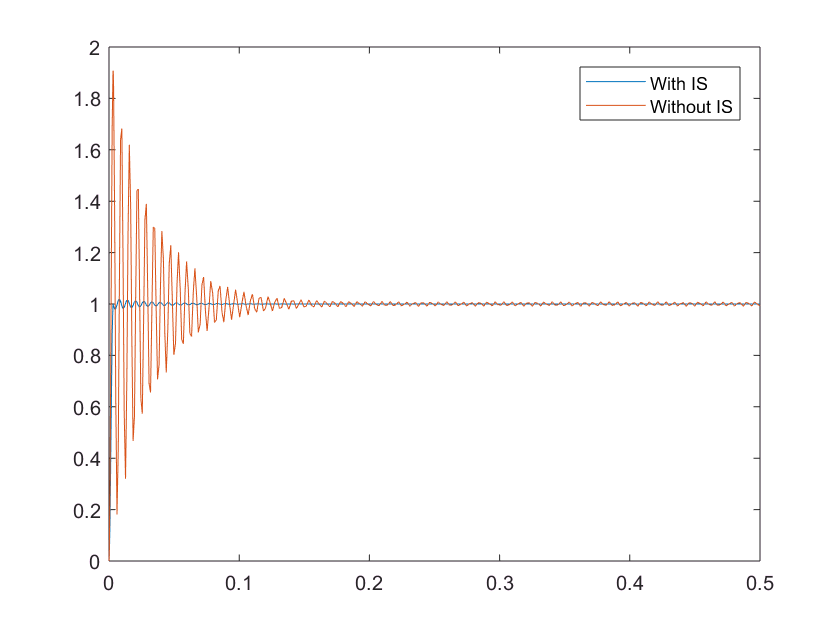

sim('IS_Simulator');
plot(ISData(:,1),[ISData(:,2) ISData(:,3)]);
legend('With IS','Without IS')

Now let's take a look at the performance with an error in the natural frequency.

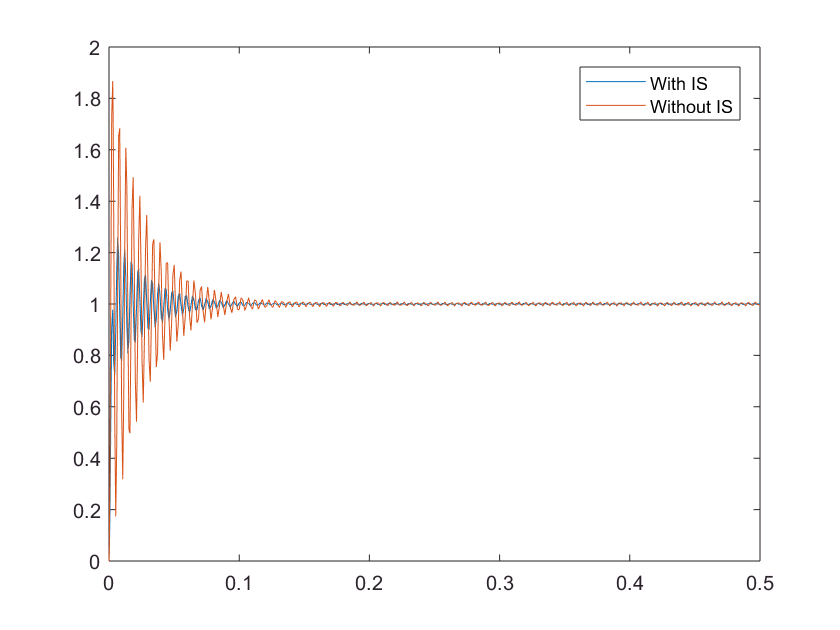

wn = 1.2*wn;  %Look at a 20% error in the natural frequency
G = tf(wn^2,[1 2*zeta*wn wn^2]);
sim('IS_Simulator');
plot(ISData(:,1),[ISData(:,2) ISData(:,3)]);
legend('With IS','Without IS')

The performance has degraded rapidly.  This is a characteristic of ZV shapers that can be improved with other constraints.

Now let's look at the performance of the ZVD shaper.  Note that there is still a 20% error in wn in the results below.

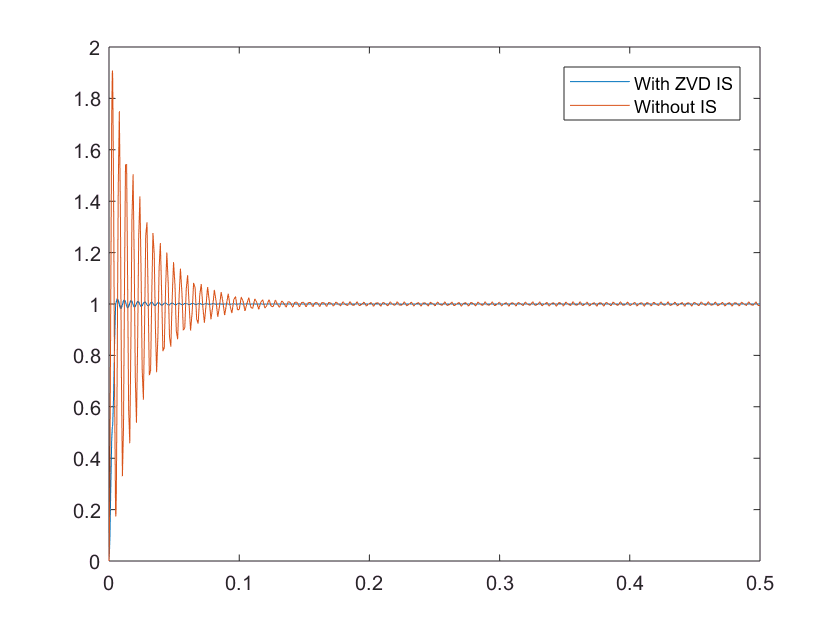

A0 = 1/(1+2*K+K^2);
A1 = 2*K/(1+2*K+K^2);
A2 = K^2/(1+2*K+K^2);
t1 = pi/wn/sqrt(1-zeta^2);
t2 = 2*pi/wn/sqrt(1-zeta^2);
sim('IS_Simulator');
plot(ISData(:,1),[ISData(:,2) ISData(:,3)]);
legend('With ZVD IS','Without IS')